# Unsupervised Learning In-Class Practice: Answer Key

## Loading and examining the data

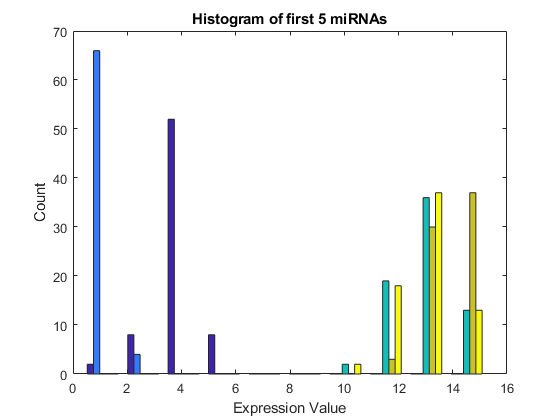

% Load the dataset
miRNA = readtable('miRNA_data.xlsx');
% Create a variable for patient IDs
patient_ID = miRNA.Patient_ID;
% Create a variable for patient health status
health_stat = miRNA.Health_Status; 
% Create a variable for miRNA names
miRNA_names = miRNA.Properties.VariableNames(3:end);
% Create a variable for miRNA expression data
miRNA_data = table2array(miRNA(:,3:end));

% Histogram of miRNA expression data
figure
hist(miRNA_data(:,1:5))
xlabel('Expression Value'); ylabel('Count')
title('Histogram of first 5 miRNAs')

Answer: The expression level for two miRNAs is much lower that the other three. In other words, the distribution of expression level for different miRNAs within this dataset may be drastically different. 

## Determining optimal k value using KMC

% Demo for k-means clustering                                 
idx = kmeans(miRNA_data,2);             % identify clusters with k-means clustering
s = silhouette(miRNA_data,idx);         % determine silhouette values 
s_score = mean(s)                       % calculate silhouette score 

s_score = 0.5539

% Create a vector of k values ranging from 2 to 10
k_values = 2:10;

% For-loop to calculate the silhouette statistic for different k values
n = length(k_values);       % number of k values
s_score = zeros(n,1);       % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    idx = kmeans(miRNA_data,k_values(i));
    % Use the silhouette function to determine silhouette values
    s = silhouette(miRNA_data,idx);
    % Calculate the silhouette score by taking the mean
    s_score(i) = mean(s);
end
table(k_values',s_score)

ans = 9×2 table
    Var1    s_score
    ____    _______
      2     0.55386
      3     0.38498
      4     0.37573
      5     0.27448
      6     0.25316
      7     0.24106
      8     0.19102
      9      0.2426
     10      0.2087

k = find(s_score==max(s_score))+1

k = 2

Answer: The max silhouette statistic is equal to 0.5539, and this corresponds with k = 2.

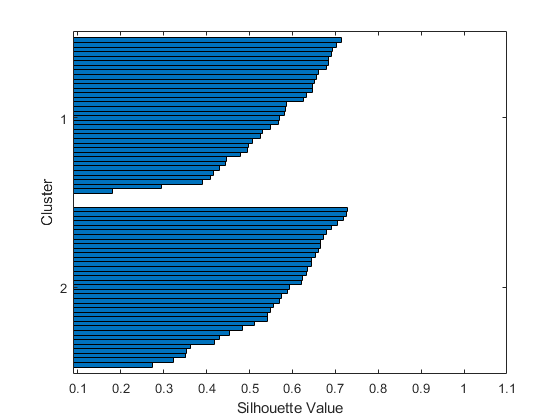

% Silhouette plot based on best k value
idx = kmeans(miRNA_data,k);
silhouette(miRNA_data,idx)

Answer: No negative values are present, but a negative silhouette value would imply that its associated observation was not well-placed into its assigned cluster. 

cluster_1 = health_stat(idx == 1)

cluster_1 = 35×1 cell array
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'diseased'}
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }

cluster_2 = health_stat(idx == 2)

cluster_2 = 35×1 cell array
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}

Answer: The patients cluster based on health status (for the most part).

## Visualizing data in lower dimension using PCA

% Do PCA (determine PC matrix, transformed data matrix, and variance explained)
[P, Y, ~, ~, explained] = pca(zscore(miRNA_data))

P =    -0.0512   -0.1726    0.4988   -0.0529   -0.2525   -0.2588    0.1990    0.6072   -0.1130   -0.0737   -0.0856    0.1193   -0.0153    0.1758   -0.2814   -0.1636   -0.0004    0.0011
   -0.0538    0.0658    0.2817    0.3763   -0.2247    0.8078   -0.1311    0.1465   -0.0039    0.0560    0.0794   -0.1334   -0.0262   -0.0317   -0.0339    0.0030    0.0038    0.0023
    0.3540    0.0105    0.1144    0.0284   -0.0034   -0.0667   -0.1342    0.0130   -0.0938    0.0853   -0.0711   -0.0803    0.0012   -0.1318    0.2117   -0.2902    0.7990   -0.1603
    0.3541    0.0121    0.1144    0.0279   -0.0069   -0.0658   -0.1320    0.0108   -0.0960    0.0829   -0.0717   -0.0848   -0.0029   -0.1392    0.2029   -0.2772   -0.2585    0.7785
    0.3536    0.0140    0.1173    0.0271   -0.0052   -0.0634   -0.1361    0.0136   -0.0990    0.0876   -0.0644   -0.0903   -0.0026   -0.1308    0.2094   -0.2899   -0.5429   -0.6067
    0.2252    0.3950    0.0401    0.0241   -0.0394   -0.0992   -0.2614   -0.0010   -0.1071 

Y =     3.5758   -1.8597    0.6174    0.0304    0.4763   -0.1809    0.3308   -0.3521    0.9954    0.3989    0.2948   -0.4299   -0.2140    0.1339   -0.3480   -0.1337   -0.0036   -0.0043
    2.8350   -1.2097    0.7042   -0.3683    1.2685   -0.0244   -0.8553    0.0629    0.0851   -0.2557   -0.0527    0.0241   -0.0716   -0.2564   -0.0799   -0.1489   -0.0004   -0.0000
    2.5258   -1.1957   -0.8401    0.6292    0.8250    0.0328    0.3044    0.6801   -0.1086    0.2544   -0.2403    0.2377    0.4051    0.2572   -0.0683    0.2456    0.0018   -0.0001
   -5.0758    0.2468   -1.1027   -2.0973   -1.3077    0.4752    1.3621   -0.7785   -0.9376   -0.0498   -0.4884   -0.5713   -0.0848   -0.3464   -0.2463    0.1572    0.0020    0.0022
   -1.3210   -0.0216    0.3544    0.2411    0.1071   -0.7362   -0.0854   -1.1232   -0.7437   -0.4331    0.8857   -0.1851   -0.1984    0.1347   -0.3199   -0.2207   -0.0078   -0.0018
   -3.3296   -0.9191    0.5818    1.0632    1.0059   -1.0223    1.2423    0.8091   -0.2404 

explained =    41.6917
   15.3567
   12.7569
    6.6834
    5.1605
    4.6021
    3.1553
    2.5146
    1.9657
    1.5768


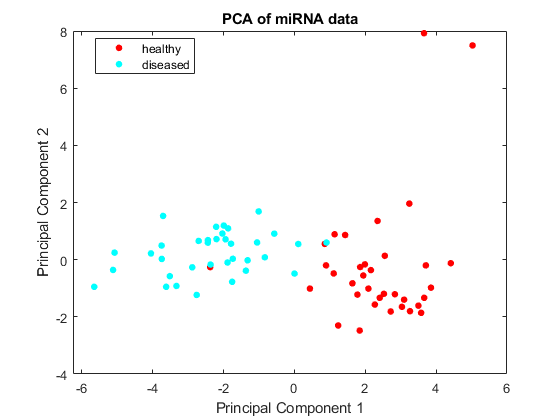

% Visualize transformed data on PC1 vs. PC2 plot (label = patient health status)
figure
gscatter(Y(:,1), Y(:,2), health_stat)
xlabel('Principal Component 1')
ylabel('Principal Component 2')
title('PCA of miRNA data')

Answer: There seems to be two clusters with two outliers. PC1 and PC2 account for 62.6% of the variance.

Answer: Yes, it seems like the clusters we see from PCA match with our results from k-means clustering if we separate the data along PC1.

% Create table of genes matched to coefficients of best PC
PC1 = P(:,1); 
table(miRNA_names',PC1)

ans = 18×2 table
          Var1             PC1   
    ________________    _________
    {'hsa_let_7f_1'}    -0.051171
    {'hsa_mir_122' }    -0.053765
    {'hsa_let_7a_1'}        0.354
    {'hsa_let_7a_2'}      0.35407
    {'hsa_let_7a_3'}       0.3536
    {'hsa_let_7b'  }      0.22522
    {'hsa_let_7c'  }      0.29136
    {'hsa_let_7d'  }     0.036003
    {'hsa_let_7e'  }      0.32396
    {'hsa_let_7f_2'}      0.25701
    {'hsa_let_7g'  }     0.010298
    {'hsa_let_7i'  }     -0.14408
    {'hsa_mir_10b' }     -0.11918
    {'hsa_mir_145' }      0.11472
    {'hsa_mir_155' }     -0.25167
    {'hsa_mir_21'  }     -0.30253

Answer: miRNA *Let*-7a2 has the greatest weight (0.3541) for PC1.

## Identifying differentially expressed miRNAs using HC

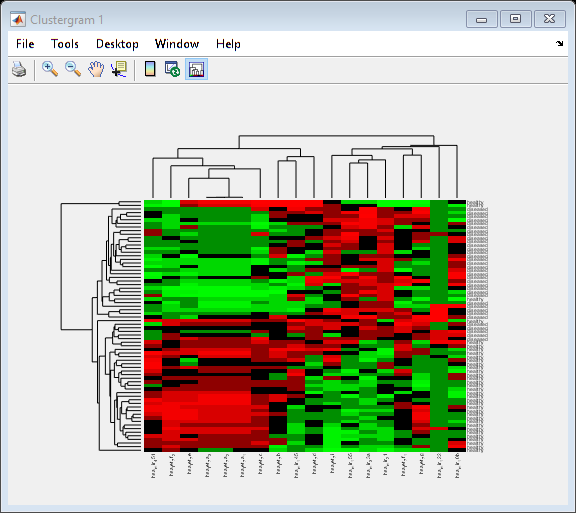

% Create clustergram (label rows, label columns, and standardize by columns)
miRNA_cg = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',miRNA_names,...
    'Standardize','column');

Answer: It seems that the outliers were picked out at the edges, but the two clusters we've seen before are not clearly separated. 

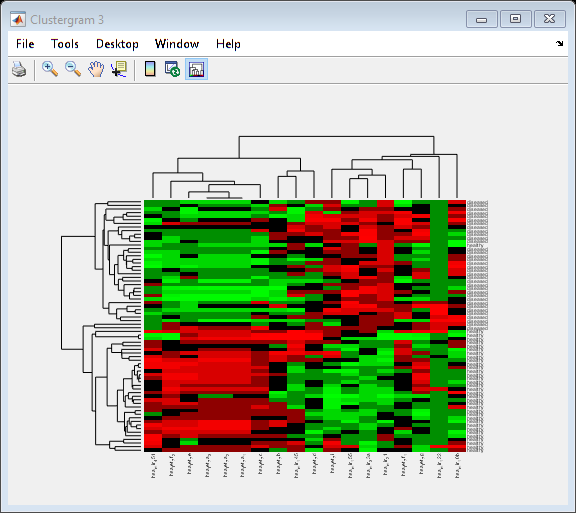

% Create clustergram (label rows, label columns, standardize by columns
% and use correlation as distance metric for rows and columns)
miRNA_cg_corr_rbc = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',miRNA_names,...
    'Standardize','column',...
    'RowPDist','correlation',...
    'ColumnPDist','correlation');

Answer: As opposed to before, this clustergram better separates patients according to their health status. This matches closer to our previous results from KMC and PCA. 

Answer: Based on the clustergram, the following miRNAs appear to be differentially expressed between healthy and diseased individuals: miR-451, *Let*-7, miR-155, miR-33a, and miR-21. 